**9.1.1 Euler方法**

`Euler``方法是求解微分方程初值问题的最简单的数值方法。将方程`$\left\lbrace \begin{array}{cc}
y^{\prime } =f\left(x,y\right) & x\in \left\lbrack a,b\right\rbrack \\
y\left(a\right)=\eta  & 
\end{array}\right.\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(9-1\right)$   

`的两端在区间`$\left\lbrack x_k ,x_{k+1} \right\rbrack$上积分，得到$\int_{x_k }^{x_{k+1} } y^{\prime } \left(x\right)\mathrm{dx}=\int_{x_k }^{x_{k+1} } f\left(x,y\left(x\right)\right)\mathrm{dx}$

即$y\left(x_{k+1} \right)=y\left(x_k \right)+\int_{x_k }^{x_{k+1} } f\left(x,y\left(x\right)\right)\mathrm{dx}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(9-2\right)$

`应用左矩形公式`$\int_a^b f\left(x\right)\textrm{dx}\approx \left(b-a\right)f\left(a\right)$，则有


$$y\left(x_{k+1} \right)=y\left(x_k \right)+h\;f\left(x_k ,y\left(x_k \right)\right)+R_{k+1}^{\left(1\right)} \;\;\;\;\;\;\left(h=x_{k+1} -x_{k+} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(9-3\right)$$


略去(9-3)中的$R_{k+1}^{\left(1\right)}$，得$y\left(x_{k+1} \right)\approx y\left(x_k \right)+h\;f\left(x_k ,y\left(x_k \right)\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(9-4\right)$

考虑到$y\left(x_0 \right)=y\left(a\right)=\eta$，设已求得$y\left(x_k \right)$的一个近似值$y_k$，则由式(9-4)可得$y\left(x_{k+1} \right)\approx y_k +h\;f\left(x_k ,y_k \right)\equiv y_{k+1}$

于是取$y_0 =\eta$，由


$$y_{k+1} =y_k +h\;f\left(x_k ,y_k \right)\;\left(k=0,1,2,\ldotp \ldotp \ldotp ,n-1\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(9-5\right)$$
   

`可依次求出`$y_k \left(k=1,2,\ldotp \ldotp \ldotp ,n\right)$`。``称式``(9-5)为求解初值问题``(9-1)的``Euler``公式。`

`根据公式(9-5)可以编写求解初值问题的Euler法的MATLAB程序Explicit_Euler.m，具体程序代码如下：`

`function [x,y]=Explicit_Euler(odefun,xspan,y0,h,varargin)`

`% 显式Euler公式求解常微分方程`

`% 输入参数：`

`%      ---odefun：微分方程的函数描述`

`%      ---xspan：求解区间[x0,xn]`

`%      ---y0：初始条件`

`%      ---h：迭代步长`

`%      ---p1,p2,…：odefun函数的附加参数`

`% 输出参数：`

`%      ---x：返回的节点，即x=xspan(1):h:xspan(2)`

`%      ---y：微分方程的数值解`

`x=xspan(1):h:xspan(2);`

`y(1)=y0;`

`for k=1:length(x)-1`

`    y(k+1)=y(k)+h*feval(odefun,x(k),y(k),varargin{:});`

`end`

`x=x';y=y';`   

`该函数的调用格式为：`

`[x，``y] =Explicit_Euler(ode``fun，``x``span，``y``0，h，p1，``p2，...)`

`【例`9-1】`利用Euler法求解以下初值问题。`


$$\left\lbrace \begin{array}{cc}
y^{\prime } =4e^{0\ldotp 8t} -0\ldotp 5y\left(0\le t\le 4\right) & \\
y\left(0\right)=2 & 
\end{array}\right.$$


`选取步长为``1``的``Euler``法进行求解，编写如下语句：`

clf
f=@(t,y)4*exp(0.8*t)-0.5*y;
[t,y]=Explicit_Euler(f,[0,4],2,0.01);    %利用Euler法求数值解
y1=dsolve('Dy-4*exp(0.8*t)+0.5*y=0','y(0)=2','t');    %求微分方程解析解

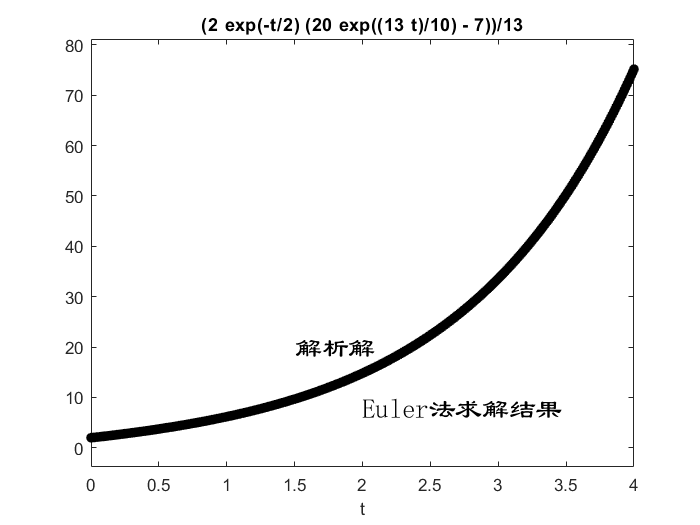

ezplot(y1,[0,4])    %绘制解析解图形
hold on    %图形保持
plot(t,y,'k.-','MarkerSize',20)    %绘制数值解图形并设置线型、颜色和标记符号
text([1.5,2],[20,8],{'解析解','Euler法求解结果'},...
'fontname','隶书','fontsize',16)    %添加标注

**9.3.3 微分方程组的MATLAB函数求解**

`MATLAB``提供了一系列函数来求解微分方程组，包括``ode``系列函数，另外还提供了几类特殊的微分方程的求解函数，例如ode15s()，ode15i()等。针对微分方程组的不同类型，MATLAB提供了相关的求解函数，用户可以利用它们很方便地求解微分方程组，这里首先给出MATLAB提供的求解微分方程组的函数及用法说明，如表9-1所示。`

`表9-1 求解微分方程组的`MATLAB`函数`

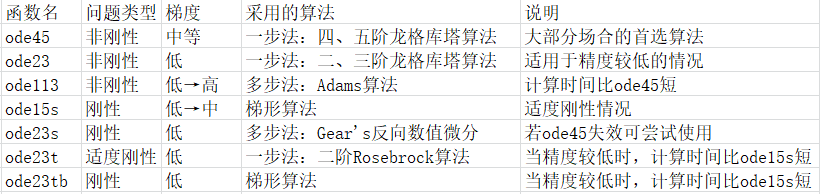

`下面介绍上述微分方程求解函数的使用方法。在上表中，除ode15i()以外的所有ode系列函数的调用格式为(这里将上述函数统称为solver)：`

sol = solver(odefun,tspan,y0,options,p1,p2,...)

[T,Y,TE,YE,IE] = solver(odefun,tspan,y0,options,p1,p2,...)

其中，odefun是显式常微分方程$y^{\prime } =f\left(t,y\right)$中的$f\left(t,y\right)$；tspan是变量的求解区间，它有两种可能，当tspan表示二元向量$\left\lbrack t_0 ,t_f \right\rbrack$时，tspan是用来定义求解数值解的时间区间；当tspan表示多元向量$\left\lbrack t_0 ,{t_1 ,\ldotp \ldotp \ldotp ,t}_f \right\rbrack$时，命令将会在tspan定义的时间序列进行数值求解，此时tspan的元素必须按照单调次序排列；y0是初值或终值条件，当$t_0 <t_f$时，y0表示初始状态变量；当$t_0 >t_f$ 时，y0表示状态变量终值；options是微分方程优化参数，它是一个结构体，使用odeset()可以设置具体参数，odeset的用法同optimset；p1，p2，...是微分方程odefun的参数赋值。输出参数T是所求数值解的自变量数据列向量；Y是所求微分方程的因变量数据矩阵；TE，YE，IE只有在设置“Event”记录时，才有相应的输出数据，具体的含义读者可参看帮助文档。

`【例`9-2】 利用ode函数求解`【例`9-1】

clf
f=@(t,y)4*exp(0.8*t)-0.5*y;
[t,y]=ode45(f,[0,4],2);    %利用Euler法求数值解
y1=dsolve('Dy-4*exp(0.8*t)+0.5*y=0','y(0)=2','t');    %求微分方程解析解

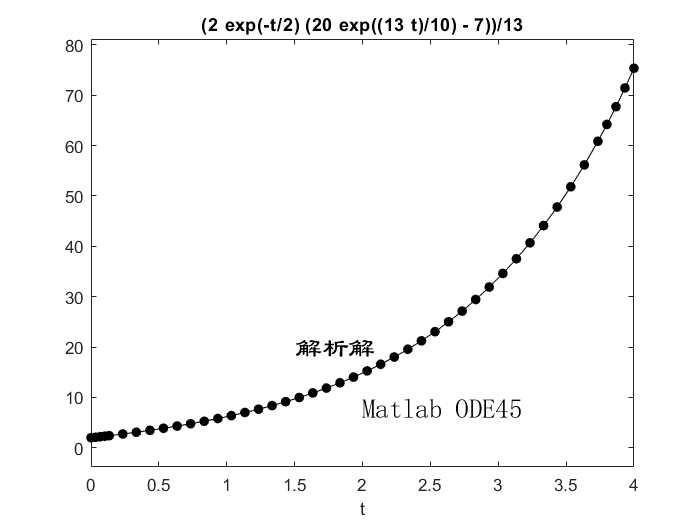

ezplot(y1,[0,4])    %绘制解析解图形
hold on    %图形保持
plot(t,y,'k.-','MarkerSize',20)    %绘制数值解图形并设置线型、颜色和标记符号
text([1.5,2],[20,8],{'解析解','Matlab ODE45'},...
'fontname','隶书','fontsize',16)    %添加标注